# Homework 06

# MATLAB Assignment

# Discrete Fourier Transform and the Inverse Discrete Fourier Transform

## Introduction

Time domain analysis can be an effective way to understand what is happening with signals, but when working in the time domain it can sometimes be difficult to distinguish individual signal frequency components when there is a lot of noise or other signals mixed together.  Therefore, we use the discrete Fourier transform to analyze signals in the frequency domain.  This can help to better separate and measure signals that have discrete frequency content.

# Computing the DFT

The real discrete Fourier transform is used to decompose a time domain signal into frequency domain components.  For a time domain signal with N points (N - even) the DFT results in a real and an imaginary output Re[k] and Im[k] each having $N/2+1$ values.

The forward DFT transforms the time domain signal into the frequency domain and then an Inverser DFT transforms the frequency domain signal into the time domain

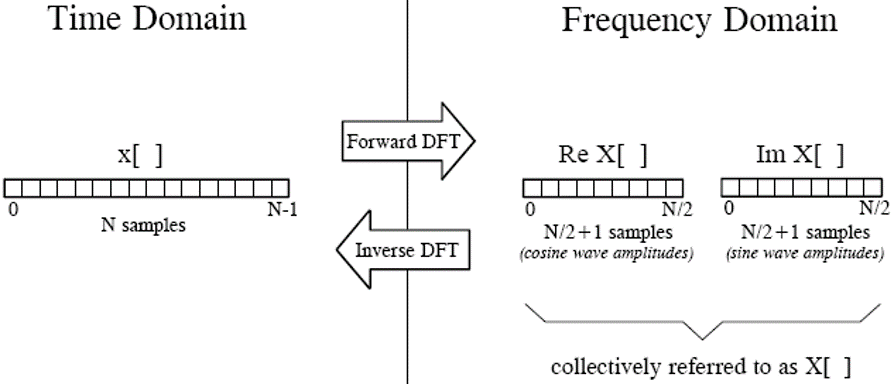

To compute the DFT, the time domain signal is multiplied point by point by a set of basis functions.  These multiplications are summed together to result in a single value.  The basis functions are a set of cosine and sine signals.  The basis functions are:

$c_k[i] = cos(2\pi k i/N)$  and


$$s_k[i] = sin(2\pi k i/N)$$


where $i$ represents the time domain sample and k represents the frequency of the COS or SIN wave.  The two parts of the DFT can be computed from


$$Re X[k] = \sum_{i=0}^{N-1} x[i] cos(2\pi k i/N)$$
  

and


$$Im X[k] = -\sum_{i=0}^{N-1} x[i] sin(2\pi k i/N)$$
 

where k ranges from 0 to N/2.

# Computing the IDFT

To compute the IDFT, the values of the frequency domain components first need to be scaled appropriately..  Each value is scaled by $N/2$ except the first and last sample corresponding to $X[0]$ and $X[N/2]$ which are scaled by N.

That is:


$$Re \bar{X}[k] = \frac{Re X[k]}{N/2}$$


$Im \bar{X}[k] = - \frac{Im X[k]}{N/2}$  (Don'f forget the negative sign)

except for two special cases:


$$Re \bar{X}[0] = \frac{Re X[0]}{N}$$


and


$$Re \bar{X}[N/2] = \frac{Re X[N/2]}{N}$$


The imaginary values for these special cases is always 0.

After the scaling then the time domain sequence can be found from:


$$x[i] = \sum_{k=0}^{N/2} Re \bar{X}[k] cos(2\pi k i /N) + \sum_{k=0}^{N/2} Im\bar{X}[k] sin(2\pi k i/N)$$


where $i$ represents the time domain sample and k represents the frequency of the COS or SIN wave.  

# Assignment Description

You are to write two MATLAB functions.  One is to compute the DFT for a real time domain sequence.  The other is to compute the IDFT to transform a frequency domain sequence into the time domain.  You will use MATLAB grader to assess your function and determine if you have correctly written the function.  MATLAB grader can be accessed through [grader.mathworks.com](http://grader.mathworks.com) .

You will log in with a Mathworks account tied to your RIT email address.  You will have had to have a Mathworks account to download and use MATLAB with the RIT license.

You will find EEET-425 DSP as one of the courses and an assignment for the DFT function under MATLAB Assignment 1.

A template for the function is given to you and an example of how to call the function.  You have an unlimited number of attempts to get your function to pass all of the test inputs. You may not use the built-in FFT function in MATLAB.

Writing this function will help you to better understand how the DFT works and you can use it for computations on Homeworks and exams.  Much easier than calculating it by hand!

After you are done writing the functions solve the problems using the functions that you created in this Live Script File

See the templates of the functions at the end of this document

# Problems

## Problem 1

A time signal consists of three sinuoids sampled at 8000 Hz.  There is a DC component and noise in the signal.  This signal can be found in the file on myCourses with the name "HW_06_Problem_1 .mat"  The signal is 1000 samples long.

Load the file into the workspace.  This will load a variable into your work space with the name "signal".  

Then using your DFT function compute the real and imaginary values of the DFT.  

Knowing that the real and imaginary values in the frequency domain represent a complex number, create a complex number out of these two vectors.

Then plot the magnitude of the frequency domain signal versus the frequency in Hz.  You will have to create a vector that contains the frequency values.

Identify the frequencies and magnitudes of the three sinusoids and the DC signal.

Were you able to identify those signals by observing the time domain signal?  Has the DFT helped to analyze this signal?

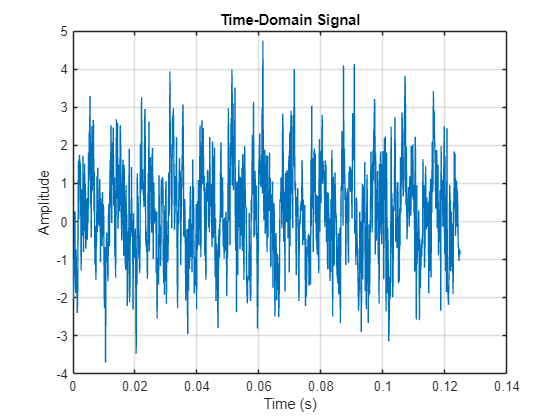

%
% A time signal consists of three sinuoids sampled at 8000 Hz.  There is a DC component and noise in the signal.
% This signal can be found in the file on myCourses with the name "HW_06_Problem_1 .mat"
%
% Load the file into the workspace.  This will load a variable into your work space with the name "signal". 
%
load('HW_06_Problem_1.mat');

fs = 8000;               % sampling frequency
N  = length(signal);     % number of samples (should be 1000)
%
% Plot the time domain signal
%
t = (0:N-1)/fs;          % time vector in seconds
figure;
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Signal');
grid on;

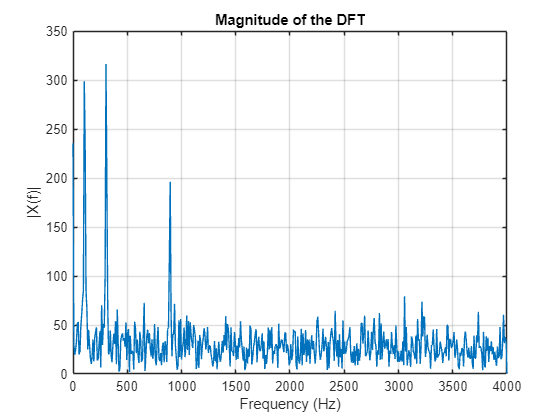


%
%  Using your DFT function compute the real and imaginary values of the DFT.
%
[ReX, ImX, debugStruct] = DFT(signal);


%
% Knowing that the real and imaginary values in the frequency domain represent a complex number, create a complex number out of these two vectors.
%

%  Place your solution here
X = ReX + 1i*ImX;

% Create the frequency axis (0 up to Nyquist)
N   = length(signal);  % if you padded by 1, you may want the original length
freqIndex = 0:(N/2);
f = freqIndex * (fs / N);   % frequency in Hz

% Plot the magnitude vs frequency
figure;
plot(f, abs(X));
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude of the DFT');
grid on;


[peakVals, peakLocs] = findpeaks(abs(X), 'SortStr','descend', 'NPeaks',4);
peakFreqs = f(peakLocs);
disp('Peak frequencies (Hz): ');

Peak frequencies (Hz): 


disp(peakFreqs);

         304         104         896        3056



disp('Peak magnitudes: ');

Peak magnitudes: 


disp(peakVals);

  316.4215  298.6471  196.0822   79.3841



## Problem 2

The inverse DFT can help us find the impulse response for a given filtering function that we are interested in creating.  The file "HW_06_Problem_2.mat " has a band stop filter response that you want to find the impulse response of for an FIR filter.

Load the file.  This will load a variable named hBSF into the work space.  This is a set of complex values representing the filter response and represents the DFT of the impulse response in cmplex format.  The sample rate of the filter is 8000 Hz

Plot the magnitude of the filter response vs the absolute frequency in Hz.  The frequency range is from 0 to the Nyquist freqeuncy.

Find the inverse DFT of the filter frequency response using your IDFT function.  Plot the impulse response of the filter.

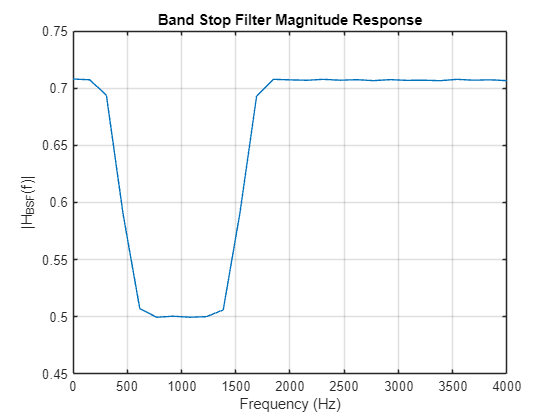

%
% Load the file.  This will load a variable named hBSF into the work space.  
% This is a set of complex values representing the filter response and represents the 
% DFT of the impulse response in cmplex format.  The sample rate of the filter is 8000 Hz
%
load('HW_06_Problem_2.mat');

fs = 8000;
N  = length(hBSF)*2 - 2;  

halfN = N/2;
k = 0:halfN;
freqHz = k*(fs/N);

Hmag = abs(hBSF);

%  Plot the magnitude of the filter response vs the absolute frequency in Hz.  The frequency range is from 0 to the Nyquist freqeuncy.
figure;
plot(freqHz, Hmag);
xlabel('Frequency (Hz)');
ylabel('|H_{BSF}(f)|');
title('Band Stop Filter Magnitude Response');
grid on;

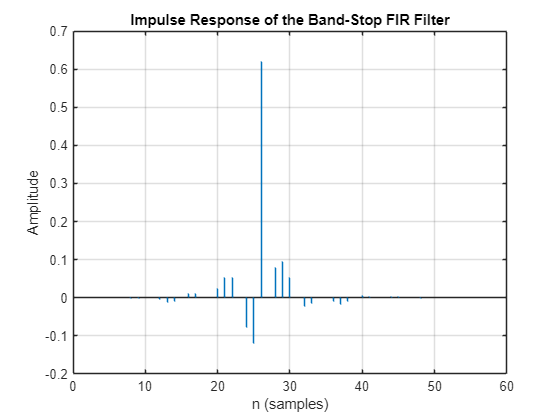


%  Find the inverse DFT of the filter frequency response using your IDFT function.  Plot the impulse response of the filter.
ReH = real(hBSF);
ImH = imag(hBSF);

% Call your IDFT
[h_imp, debugIDFT] = IDFT(ReH, ImH);

% h_imp is the impulse response in the time domain
figure;
stem(h_imp, 'Marker','none');  % or plot(...) for a continuous-like view
xlabel('n (samples)');
ylabel('Amplitude');
title('Impulse Response of the Band-Stop FIR Filter');
grid on;

# Function Templates

Here is a copy of the template for the DFT function  (commented out).  Select all then CTRL^T to uncomment.  The template are also included in MATLAB Grader.

% %
% %  Modify the code below to implement the DFT function.  Comments are included to guide you to your solution.
% %
% function [ReX, ImX, Debug] = DFT( inputX )
% %
% %  Function DFT
% %
% %  The Discrete Fourier Transform takes a discret time (sample) domain
% %  input and transforms it into values of COSINE and SINE functions in the
% %  frequency domain.  
% %
% %  Input Arguments
% % 
% %  inputX -- A row vector of time domain samples.  There must be an even
% %            number of samples
% %
% %  Output Arguments
% %
% %  ReX -- The magnitude of the COS functions computed for each discrete
% %         frequency k from 0 to N/2.  There will be N/2+1 values
% %
% %  ImX -- The magnitude of the SIN functions computer for each discrete 
% %         frequency k from 0 to N/2.  There will be N/2+1 values.
% %
% %  Optional output Arguments
% %
% %  Debug -- Debug is a MATLAB structure that you can assign internal variables to
% %  so that you can see them in the calling function.  This will help you debug your code.
% %  See the details below on how to used Debug.
% 
% %  Define the Debug variable as a struct.  This is to return variables to the 
% %  calling function for assessment purposes.
% %  You may use this by creating a field in the structure using the 'dot' notation
% %  For example if you wanted to pass the intermediate value of a variable back to
% %  calling function you would use the syntax 
% %  debug.variableName = variable;
% %  Then in the calling function you could display the variable debug.variableName 
% %  to check it's value
% Debug = struct;
% 
% 
% %  Initialize each element in each variable to a value of 0
% %
% 
% %  Create a variable numPoints that is the number of points in the input.
% %  Use the length() function to find the number of points in the input
% 
% numInputPoints = 
% 
% % Reshape to a row vector (or make sure its a row vector )
% %  Use the reshape command
% 
% inputX = reshape(  %  Complete by adding your code here to make sure the input vector is a row vector
% 
% %   Check for an even number of input points.  Zero-pad if odd
% %  Try using the mod function to test for even/odd
% 
% if mod( numInputPoints   %  Complete by adding your code here to test for an even/odd sequence length and pad if necessary
%     
%     
% end
% 
% 
% %  Create a variable for the real and the imaginary part of the output X
% %  called ReX and ImX respectively.  These are also the return arguments
% %
% %  Initialize them to a column vector that is the number of input points divided
% %  by 2 + 1.
% %
% %  You can use the zeros(M,N) function to create a MXN matrix of zeros (a
% %  column vector is an MX1 matrix)
% %
% 
% ReX = 
% ImX = 
% 
% % Create two "for" loops
% % 
% % The first loop iterates a variable (call it "k") over the frequency index that 
% % goes from 0 to N/2 in steps of 1.
% %
% % The second loop interates a variable (call it "i") over time that goes from 0
% % to N-1
% %
% % The values of ReX and ImX are computed by summing the each time domain
% % sample by the value of either the COSINE (for the real part) or
% % SINE term (for the imaginary part).
% % 
% % Refer to the example written in BASIC in the text
% %
% %  Important - Remember that MATLAB indices start at 1 whereas we are
% %  iterating "k" and "i" starting at 0.  You will need to adjust the index
% %  to ReX and ImX accordingly
% 
% 
% for k = 
%     
%     for i = 
%         
%         ReX(k+1) =
%         ImX(k+1) = 
%         
%         
%     end
% end
% 
% 
% end





Here is a copy of the template for the IDFT function (commented out).  Select all then CTRL^T to uncomment. The template are also included in MATLAB Grader.

% function [xOut, Debug] = IDFT( ReX, ImX )
% %
% %  IDFT function
% %
% %  The function will compute the IDFT from the two sequences representing
% %  the real and imaginary parts of the DFT.  There are N/2+1 samples in the
% %  DFT.
% %
% %  Input Arguments
% %
% %  ReX -- The sequence of the DFT representing the real part.  N/2+1
% %         samples
% %
% %  ImX -- The sequence of the DFT representing the imaginary part.  N/2+1
% %         samples
% %
% %  Output Arguments
% %
% %  outX -- The time domain sequence after finding the IDFT.  N samples in
% %          length
% %
% %  Optional output Arguments
% %
% %  Debug -- Debug is a MATLAB structure that you can assign internal variables to
% %  so that you can see them in the calling function.  This will help you debug your code.
% %  See the details below on how to used Debug.
% 
% %  Define the Debug variable as a struct.  This is to return variables to the 
% %  calling function for assessment purposes.
% %  You may use this by creating a field in the structure using the 'dot' notation
% %  For example if you wanted to pass the intermediate value of a variable back to
% %  calling function you would use the syntax 
% %  debug.variableName = variable;
% %  Then in the calling function you could display the variable debug.variableName 
% %  to check it's value
% Debug = struct;
% 
% 
% %  Begin by creating a variable that is the number of points N in the time
% %  domain sequence.
% %
% %  N/2 + 1 points in the frequency domain will result in N points in the
% %  time domain sequence.  Compute the number of points in the time domain
% %  sequence.  Name the variable numPoints (instead of just N)
% 
% numPoints = 
% 
% % Reshape the input to a row vector (or make sure its a row vector )
% ReX = reshape( %....
% ImX = reshape( %....
% 
% % Scale the values of the DFT inputs
% 
% % Begin by initialzing ReX_bar and
% % ImX_bar to zero.  Then compute the scaled value.  Don't forget the
% % negative sign on the imaginary component.
% 
% ReX_bar = zeros( %....
% ImX_bar = zeros( %....
% 
% 
% 
% %  Apply the scale factors to the input values.  Apply the scale values from the problem description
% %  Be sure to check for the special conditions and apply the correct scale value.
% 
% for k = 0:numPoints/2
%     %  Put your scaling code here
%     
% end
% 
% %  Save debug return variables for assessment and checking.  The following two lines
% %  save the scaled DFT input values that are used in the assessment.  The lines are locked
% %  so they can't be changed
% %
% %  You may use the debug structure to pass other internal variables back to your calling code.  Don't modify
% %  this code below, but add your own variables.  Use the structure 'dot' syntax which is
% %  debug.variableName = variable
% 
% Debug.ScaledReal = ReX_bar;   %  Save for debug
% Debug.ScaledImag = ImX_bar;   %  Save for debug
% 
% %  Initialize the output variable 'xOut' to all zeros. This will be a row vector numPoints long
% 
% xOut = 
% 
% 
% %  Iterate the time (sample) from 0 to the total number of time domain points
% %  less one (numPoints - 1).  Then for each time iteration
% %  iterate through all the frequency values from 0 to N/2.
% %  
% %  Compute the IDFT by multiplying the basis functions (cosine and sine) at the 
% %  desired frequency and time step by the DFT coefficients.  Keep a running
% %  accumulation of the values to find the time domain value at each index.
% %
% %  Be cognizant of the MATLAB indexing here.  MATLAB starts at 1
% %
% 
% for i = 0:numPoints-1
%     
%     for k = 0:numPoints/2
%          %  Add your IDFT code here
%         
%     end
% end
% 
% 
% 
% 
% end
% 